%% 1.3  Chapra 22.17  Temperature change in a corpse
Ta=20; %ambient temperature
To=37; %normal body temperature at time of death, t=0;
Tx=29.5; %body temp when body was discovered, t=x;
Tx2=23.5; %body temp 2 hr after discovery
% Equations to compute x and K

%dT/dt = -K( T-Ta )


x=    2*( log( (Tx-Ta)/(To-Ta) ) ) / ( log( (Tx2-Ta)/(Tx-Ta) ) )   %time body found, hr

x =    1.165557824474549

K=    (-1/2) * ( log( (Tx2-Ta)/(Tx-Ta) ) )   %K, units = hr^-1

K =    0.499264415055564

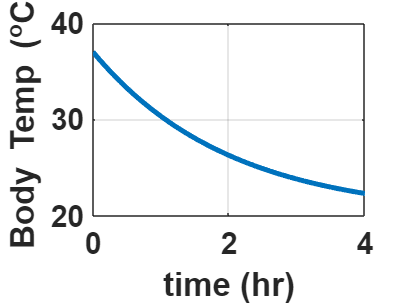


%define differential equation
temp=@(t,y,K)    ( -K*(y-Ta) )   ;
%set up time duration, tspan
tspan=[0 4];
%solve ode--if using extra parameters, use empty bracket [] before extra parameter.
[t,y]=ode45(  temp, tspan, To , [],  K   );

%% Plot solution
figure
plot(t,y,'-','linewidth',3);
xlabel('time (hr)')
ylabel('Body Temp (^oC)');
set(gca, 'fontsize',18,'fontweight','bold');
grid on

% Define given values
Ta = 20; % ambient temperature
To = 37; % normal body temperature at time of death, t=0;
Tx = 29.5; % body temp when body was discovered, t=x;
Tx2 = 23.5; % body temp 2 hr after discovery

% Equations to compute x and K
x = 2*log((Tx-Ta)/(To-Ta))/log((Tx2-Ta)/(To-Ta)) % time body found, hr

x =    0.736399642087107

K = (Tx-Ta)/(To-Ta)/exp(-x*log((Tx2-Ta)/(To-Ta))/2) % K, units = hr^-1

K =    0.312283737024222

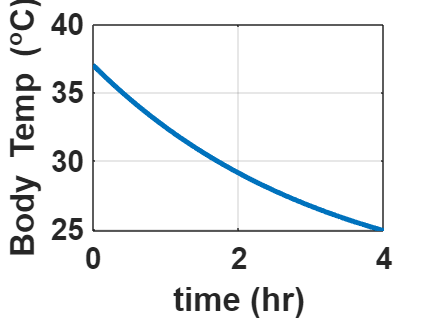


% Define differential equation
temp = @(t,y,K) -K*(y-Ta);

% Set up time duration, tspan
tspan = [0 4];

% Solve ODE using ode45
[t,y] = ode45(temp,tspan,To,[],K);

% Plot solution
figure
plot(t,y,'-','linewidth',3);
xlabel('time (hr)')
ylabel('Body Temp (^oC)');
set(gca, 'fontsize',18,'fontweight','bold');
grid on


% Check temperatures at different times
disp(['Body temperature at time of death (t=0): ' num2str(To) ' ^oC'])

Body temperature at time of death (t=0): 37 ^oC


disp(['Body temperature when discovered (t=x): ' num2str(Tx) ' ^oC'])

Body temperature when discovered (t=x): 29.5 ^oC


disp(['Body temperature 2 hours after discovery (t=x+2): ' num2str(Tx2) ' ^oC'])

Body temperature 2 hours after discovery (t=x+2): 23.5 ^oC
